I = 0.5;
k_I = 0.1867;
k_mI = 0.7801;
k_A = 0.9833;
k_B = 0.8252;
k_mB = 0.5157;
k_1 = 0.3132;
k_m1= 0.5770;
k_2 =0.3700; 
k_m2 = 0.1090; 
delta_1 = 0.0697; 
delta_2 = 0.0226;

%set k_mA to some relevant value where you're plotting trajectories 
k_mA = 0.2;


function dydt = nf1(t,y, I, k_I, k_mI, k_A, k_B, k_mA, k_mB, k_1, k_m1, k_2, k_m2, delta_1, delta_2)
% y(1) is a, y(2) is b
% Solve the ODE   (below  x=y(1) and y=y(2))
% I = params(1);
% k_I = params(2);
% k_mI = params(3);
% k_A = params(4);
% k_B = params(5);
% k_mB = params(6);
% k_1 = params(7);
% k_m1= params(8);
% k_2 = params(9); 
% k_m2 = params(10);
% delta_1 = params(11);
% delta_2 = params(12);
% dydt(1) = (k_I*I*(1-y(1)) )./(k_mI + 1 - y(1) );
% dydt(2) =  (k_B*y(2)*(1-y(2)))./(k_mB + 1 - y(2) );

%define da/dt then db/dt
dydt = [ ((k_I*I*(1-y(1)) )./(k_mI + 1 - y(1))) + ((k_A*y(1)*(1-y(1)))./(k_mA + 1 - y(1))) - ((k_2*y(1)* y(2))./(k_m2+ y(1))) - (delta_1*y(1)) ;
    ((k_B*y(2)*(1-y(2)))./(k_mB + 1 - y(2))) + ((k_1*y(1)*(1-y(2)))./(k_m1 + 1 - y(2))) - (delta_2*y(2)) ];
end

aval = 0:.05:1;
bval = 0:.05:1;

%define mesh grid for a and b, specified as ap and bp
[am,bm]=meshgrid(aval,bval);
ap = (k_I*I*(1-am) )./(k_mI + 1 - am ) + ((k_A*am*(1-am))./(k_mA + 1 - am)) - ((k_2*am* bm)./(k_m2+ am)) - (delta_1*am) ;
bp =  (k_B*bm*(1-bm) )./(k_mB + 1 - bm ) + ((k_1*am*(1-bm))./(k_m1 + 1 - bm)) - (delta_2*bm) ;
sza = sqrt(ap.^2+bp.^2);



tend = 999999;
%[A B] 
%SET BELOW !!!
y0 = [0.342 0.9872]

y0 =    0.342000000000000   0.987200000000000


tspan = [0 tend]

tspan =            0       99999


[tx,exsolx] = ode45(@(t,y) nf1(t, y, I, k_I, k_mI, k_A, k_B, k_mA, k_mB, k_1, k_m1, k_2, k_m2, delta_1, delta_2), tspan, y0);


%example below...
% function dydt = odefcn(t0,y,A,B)
%   dydt = zeros(2,1);
%   dydt(1) = y(2);
%   dydt(2) = (A/B)*t.*y(1);
% end
% 
% A = 1;
% B = 2;
% tspan = [0 5];
% y0 = [0 0.01];
% [t,y] = ode45(@(t,y) odefcn(t,y,A,B), tspan, y0);

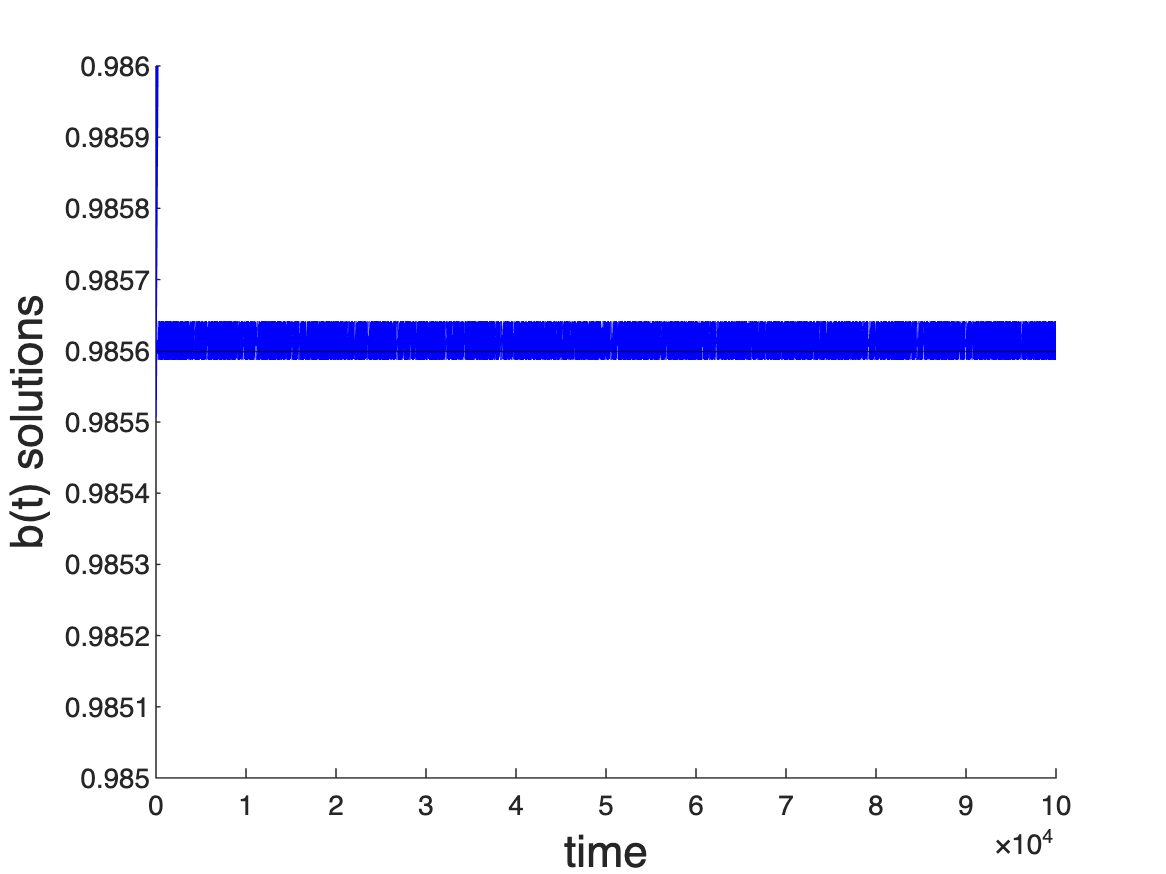

%b(t) only

figure 
hold on
% %CHANGE LIMITS AS NEEDED
%ylim([0.985 0.99])
ylim([0.985 0.986])
plot(tx,exsolx(:,2),'b-','linewidth',2)
xlabel('time','FontSize',16);
ylabel('b(t) solutions','FontSize',16)
format long 
str = sprintf("Solution trajectory (%d, %d)", y0(1), y0(2));
sol = 0.985599;
yline(sol, 'k', 'FontSize',16)

%title(['solution trajectory of B (', num2str(y0(1)), ', ', num2str(y0(2)), ')' ])

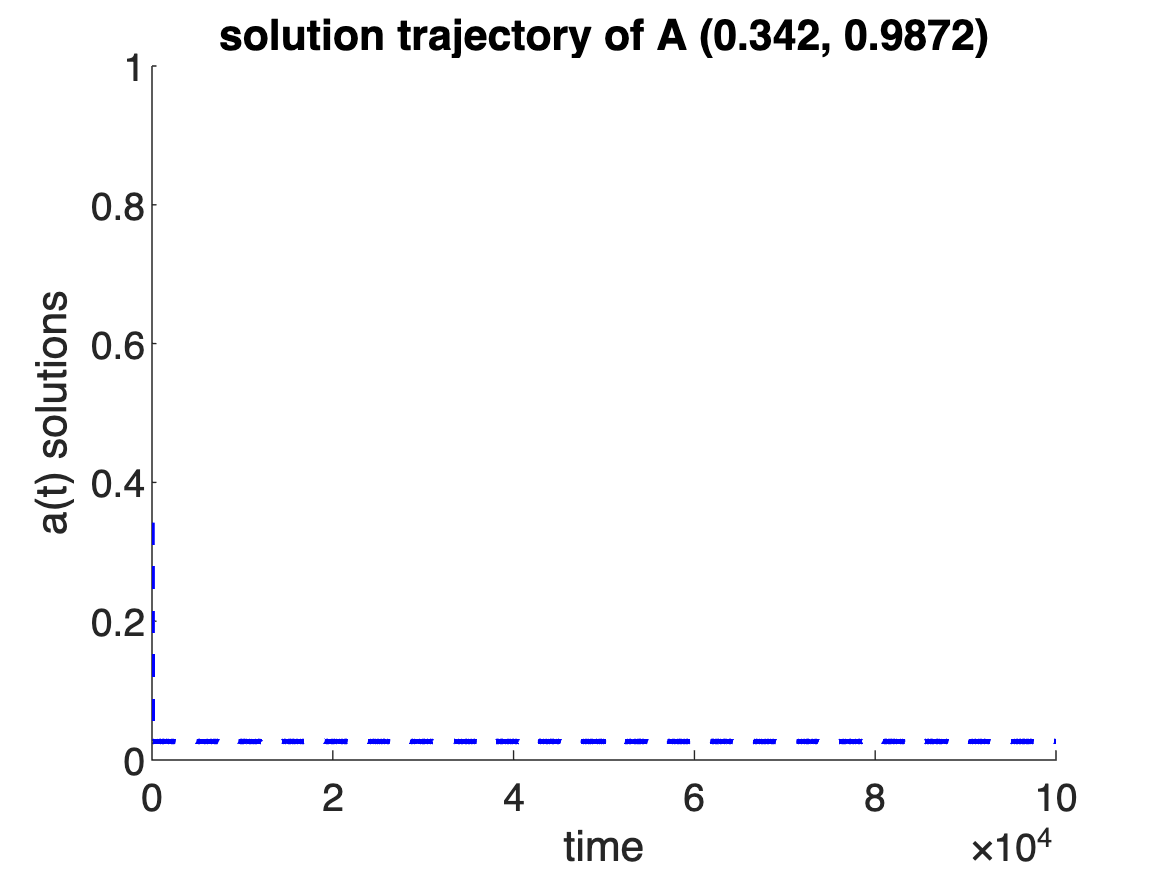


figure 
hold on
% %CHANGE LIMITS AS NEEDED
ylim([0 1])
plot(tx,exsolx(:,1),'b--','linewidth',2)
xlabel('time');
ylabel('a(t) solutions')
set(gca,'fontsize',14)
format long 
str = sprintf("Solution trajectory (%d, %d)", y0(1), y0(2));
title(['solution trajectory of A (', num2str(y0(1)), ', ', num2str(y0(2)), ')' ])

[pks,locs] = findpeaks(exsolx(:,2),tx);
[pks_min, locs_min] = findpeaks(-exsolx(:,2),tx)

pks_min =   -0.986398923767234
  -0.986866638345528
  -0.986944753361720
  -0.986845488299805
  -0.986545675352490
  -0.986262247387826
  -0.986511177205865
  -0.986542062433395
  -0.986180829126262
  -0.985614946097537


locs_min = 1.0e+04 *

   0.000125672709370
   0.000339075901133
   0.000514536865916
   0.000704466642781
   0.000921011043788
   0.001144075052689
   0.001347065755448
   0.001530514400960
   0.001719158021588
   0.002691532018881


%SET CUTOFF
cutoff = 30;
pks = pks([cutoff:end]);
locs = locs([cutoff:end]);
%SET Y_SOLUTION
sol = 0.985599

sol =    0.985599000000000


%sol = 0.9888
pks_min = pks_min([cutoff:end]);
locs_min = locs_min([cutoff:end]);

figure
hold on
%CHANGE BELOW
ylim([0.9855 0.9857]);
%ylim([0.9875 0.99]);

clear fit
%fit to exponetntial
f = fit(locs,pks,'exp1')

f =      General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.9856  (0.9856, 0.9856)
       b =   7.551e-15  (-2.331e-12, 2.346e-12)

f_min = fit(locs_min, -pks_min, 'exp1')

f_min =      General model Exp1:
     f_min(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.9856  (0.9856, 0.9856)
       b =  -3.814e-14  (-2.271e-12, 2.194e-12)

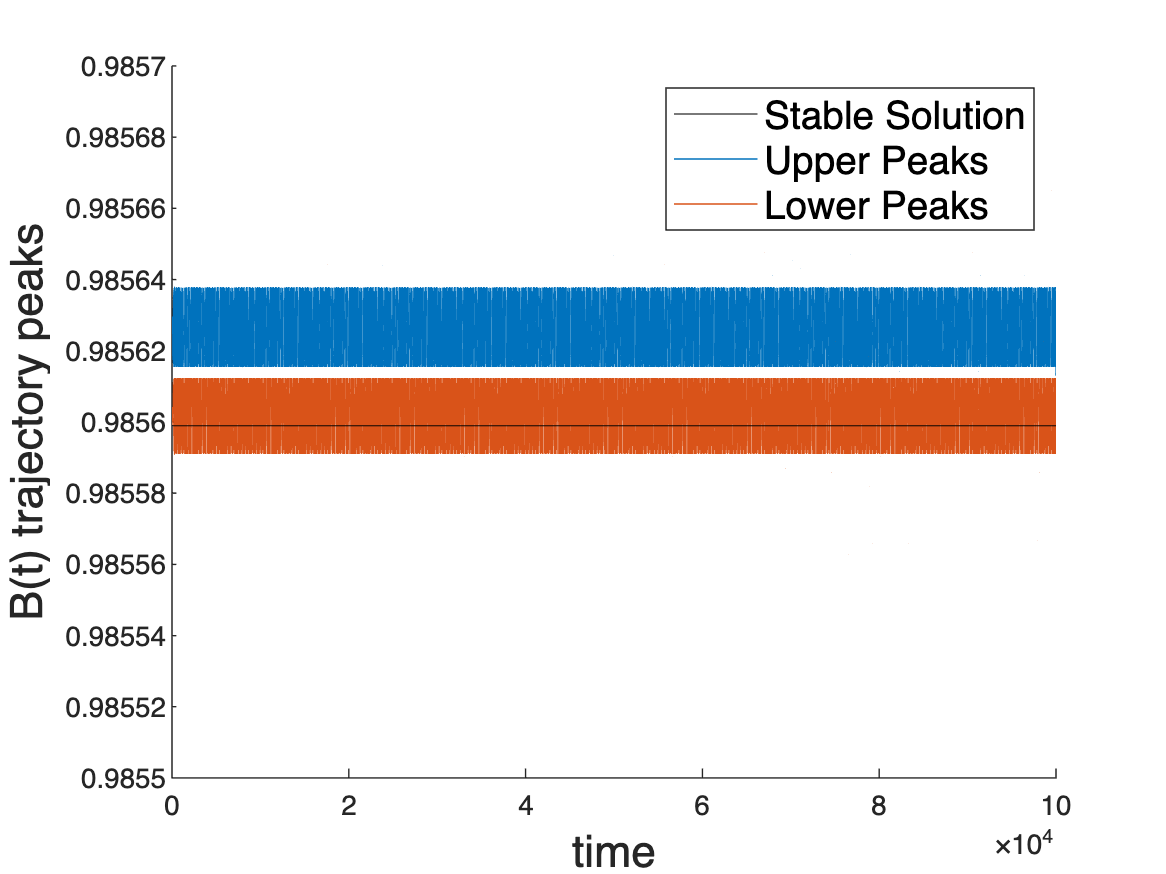

%plot(f,locs, pks)
%plot(f_min, locs_min, -pks_min)
%CHANE BELOW
yline(sol, 'k', 'FontSize',16)
plot(locs, pks)
plot(locs_min, -pks_min)
xlabel('time', 'FontSize',16);
ylabel('B(t) trajectory peaks', 'FontSize',16)
%legend('Upper Peaks', 'Upper Curve Fit', 'Lower Peaks', 'Lower Curve Fit', 'Stable Solution','FontSize',14, 'Location','southeast')
% plot(locs,pks)
% plot(locs_min, -pks_min)
legend('Stable Solution','Upper Peaks','Lower Peaks','FontSize',14)


syms x;
a =      0.9892;
b =  -3.32e-13;
equation = a*exp(b*x) == sol;

% ADJUST EQ ABOVE
converges_upper = vpasolve(equation,x)

$$converges\_upper = 10984811683.464258066114835219335$$


syms x;
 a =      0.9885;
b =   3.125e-14;
clear equation
equation = a*exp(b*x) == sol;
converges_lower = vpasolve(equation,x)

$$converges\_lower = -94050062154.259043995724963157265$$





% [alpha,b] = polyfit(locs, log(pks), 1)
% 
% fit = polyval(alpha,locs,b);
%plot(locs,fit,'-',locs,log(pks),'+');



% figure 
% hold on
% %CHANGE LIMITS AS NEEDED
% ylim([0.985 0.99])
% plot(tx,exsolx(:,1),'b--','linewidth',2)
% plot(tx,exsolx(:,2),'b-','linewidth',2)
% xlabel('time');
% ylabel('a(t),b(t) solutions')
% legend('a(t)','b(t)');
% set(gca,'fontsize',14)
% format long 
% str = sprintf("Solution trajectory (%d, %d)", y0(1), y0(2));
% title(str)
%title('solution trajectory ({y0(1)}, bleh) as function of time')


% 
% TODO:
% [pks, loc], which is [y, t]  = findpeaks(signal)
% See if it has form ae^(alpha * t)
% Do polyfit(x, log(y), 1) will fit log of y to line , get [alpha, b], wehre b where it reaches 0, and alpha is decay
% 